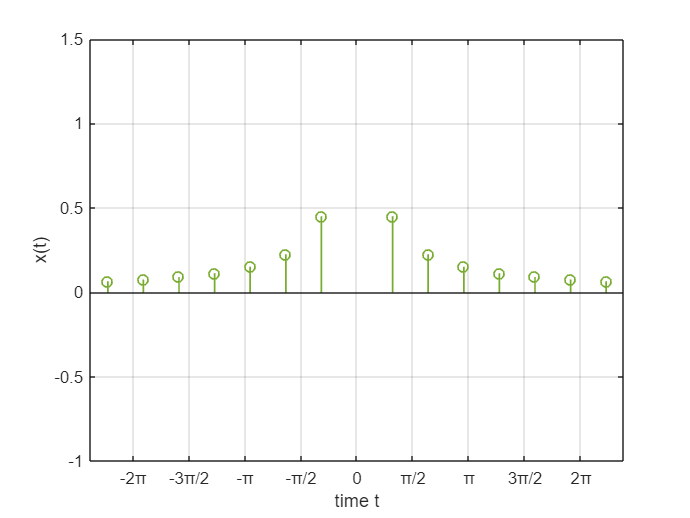

% Define the time values
t = -3*pi:0.005:3*pi; % Time values from -5 to 5 with a step of 0.01
n = -40:1:40;

% Create the unit step function
u = @(a) (a>=0);

H = @(w) sin(4*w)/w;
F = @(n) (1-j)./(n*pi);
y = @(t) (0<=mod(t,8)).*(mod(t,8)<4).*8/pi;


% Plot the function
plot(t, abs(H(t)),'LineWidth',1)
ylim([-1 1.5])
xlim([-7.5 7.5])
ylabel('x(t)')
xlabel('time t')
set(gca,'XTick',-3*pi:pi/2:3*pi)
set(gca,'XTickLabel',{'-3π','-5π/2','-2π','-3π/2','-π','-π/2','0','π/2','π','3π/2','2π','5π/2','5π'})
grid on

hold on
stem(n, abs(F(n)),'LineWidth',1)
hold off

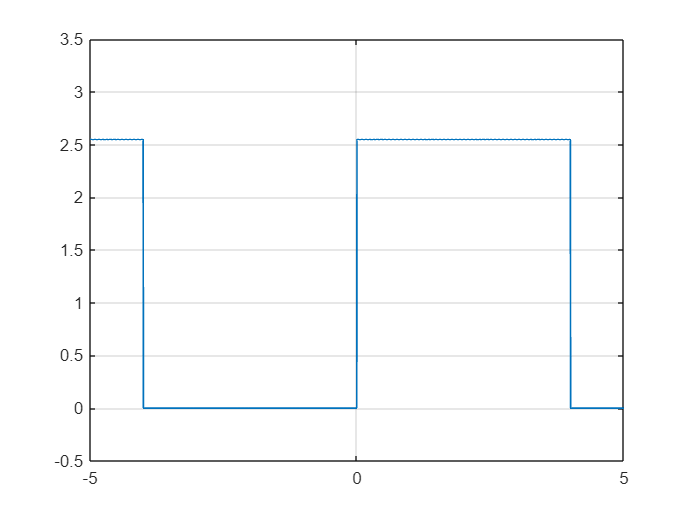



plot(t,y(t),'LineWidth',1)
ylim([-.5 3.5])
xlim([-5.00 5.00])
grid on